clear all
[data,numChan,labels,txt,fs,gain,prefiltering,ChanDim] = eeg_read_bdf("C:\Users\Peter\Desktop\CGX\data\성근창\ex_1.bdf",'all','n');

Run_start = find(data(27,:) == 3)
Class_1 = find(data(27,:) == 1)
Class_2 = find(data(27,:) == 2)

cue_offset = 625; % 1.25sec * 500Hz
imagery_duration  = floor(2.75*500); % 3sec * 500Hz
rear_offset = cue_offset + imagery_duration;

channel_selection = 1:19;

for i = 1:length(Class_1)
    group_1(i,:,:) = data(channel_selection,Class_1(i)+cue_offset:Class_1(i)+rear_offset);
    Y1(i,1) = 1;
end

for i = 1:length(Class_2)
    group_2(i,:,:) = data(channel_selection,Class_2(i)+cue_offset:Class_2(i)+rear_offset);
    Y2(i,1) = 1;
end

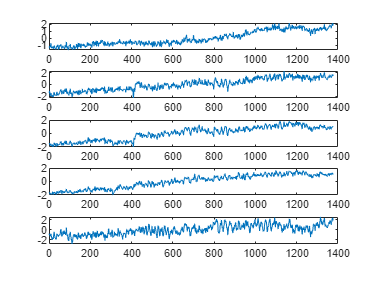

tmp = squeeze(group_1(1,:,:))';
tmpp = my_normalization(tmp);

figure
for i = 1:5
    subplot(5,1,i)
    plot(tmpp(:,i)); hold on;
end

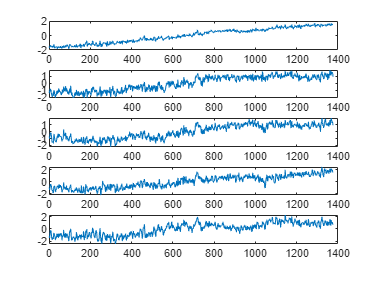

tmp = squeeze(group_2(1,:,:))';
tmpp = my_normalization(tmp);

figure
for i = 1:5
    subplot(5,1,i)
    plot(tmpp(:,i)); hold on;
end

function n_signal = my_normalization(s)
Mean = mean(s);
Std = std(s);

n_signal = (s - Mean)./Std;
end


function [K, A] = my_SAX(s,m)
n_signal = my_normalization(s);
q = floor(length(n_signal)/m);
K = [];
A = [];
for j = 1:m
    t = q*(j-1):q*j;
    v = n_signal(t+1,:);
    v_bar = mean(v);
    t_bar = mean(t);

    k_son = (t - t_bar)*(v - v_bar);
    k_mom = sum((t - t_bar).^2);

    k = k_son / k_mom;
    b = v_bar - k*t_bar;

    a = k*t_bar + b;

    K = [K k'];
    A = [A b'];
    %     A = [A a'];
end

end